# Saving and Exporting Files & Figures

There are oftentimes multiple ways to accomplish a task in MATLAB. Of course, you can always write some code to complete your task programmatically. But what if you do not know the code needed to get your results? Try solving your problem with MATLAB's interactive tools, and use those tools to automatically generate the code you need in the future.

**PDF (vectorized)**

From one of your figure windows, choose what file format you want to save or export your figure as. 

To save your figure as a vector pdf - a file type that allows for near infinite resolution in a manageable file size, go to Save As > Export to > PDF and select "Vector" under Content type.

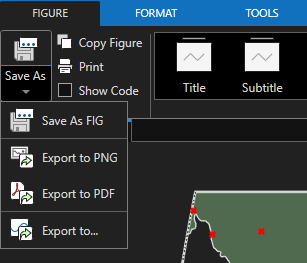

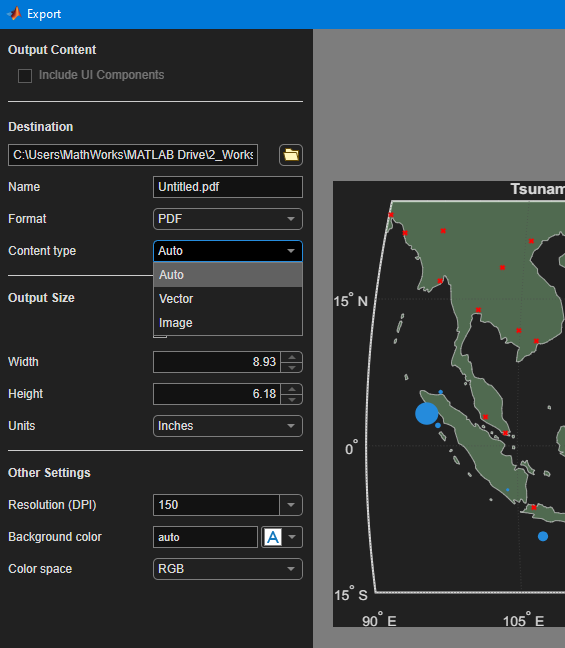

## **Exporting data in common Earth science file formats**

### **Shape Files**

We used `shaperead `to read shape file data into our workspace. Now, we can use [`shapewrite`](https://www.mathworks.com/help/map/ref/shapewrite.html?searchHighlight=shapewrite&s_tid=srchtitle_support_results_1_shapewrite) to export shape file data.

shapeinfo("worldrivers.shp")
figure
axesm('MapProjection','miller','frame', 'on', 'grid', 'on')
axis off

geoshow(GT)
hold on
plotm(coastlat,coastlon,'w')

Import the shapefile as a geospatial table. Remember from the previous worksheet that you can import as a shapefile or a geotable. Once you've loaded your data, use the code

to remove rows of the table that only have " " as the name. Then write your shape to a new file called "noBlanks". 

### NetCDF Files

#### Import

Just as we used `shaperead/write` for importing and saving .shp files, we can use functions such as `xlmread/write`, `ncread/write`, `geotiffread/write`, or `readgeoraster `for working with their respective file formats. Many file formats also have additional functions dedicated to extracting and manipulating the specific data that they commonly store. For full documentation on MATLAB-supported raster GIS and geospatial data files, [explore here](https://www.mathworks.com/help/map/file-import-and-export.html?s_tid=CRUX_lftnav).

Let's see how the Import Data task can help us again, this time with netCDF files.

% Create a structure to store imported netCDF data
aler_19521104 = struct();

filename = "C:\Users\MathWorks\MATLAB Drive\2_Workshops\LSK's Mapping and Data Analysis\Data\aler_19521104.nc";

clear filename

% Display results
aler_19521104


#### Export

To export or create a netCDF file in its most basic form, simply run:

nccreate('myfile.nc','myvar')

For more ways to write, merge, and change the format of netCDFs, see [this documentation](https://www.mathworks.com/help/matlab/import_export/exporting-to-network-common-data-form-netcdf-files.html).